**Input**

% Define Cutoff frequency for this EMI Filter
Fcutoff = 5e3

Fcutoff = 5000

% Output impedance of the filter should be much less that input impedance
% of the power supply
% Set input impedance of the power supply:
Zpowerin = 20

Zpowerin = 20

Zfilterout = 1/10*Zpowerin

Zfilterout = 2


%Maximum theoretial Capacitance
Cmax = 100e-6

Cmax = 1.0000e-04


%Calculated Cmin
Cmin = 1/(2*pi*Fcutoff*Zfilterout)

Cmin = 1.5915e-05


%Calcilated Lmin and Lmax
Lmax = 1/(Fcutoff^2*2^2*pi^2*Cmin)

Lmax = 6.3662e-05

Lmin = 1/(Fcutoff^2*2^2*pi^2*Cmax)

Lmin = 1.0132e-05

**Capacitance and Indutance**

L = 10.^(-9:-3) 

L = 1.0e-03 *

    0.0000    0.0000    0.0001    0.0010    0.0100    0.1000    1.0000


C = 10.^(-9:-3)

C = 1.0e-03 *

    0.0000    0.0000    0.0001    0.0010    0.0100    0.1000    1.0000


f = 10.^(0:6)

f =            1          10         100        1000       10000      100000     1000000


**Impedances**

Xl = 2*pi.*f'*L

Xl = 1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006
    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0063
    0.0000    0.0000    0.0000    0.0001    0.0006    0.0063    0.0628
    0.0000    0.0000    0.0001    0.0006    0.0063    0.0628    0.6283
    0.0000    0.0001    0.0006    0.0063    0.0628    0.6283    6.2832


Xc = 1./(2*pi.*f'*C)

Xc = 1.0e+08 *

    1.5915    0.1592    0.0159    0.0016    0.0002    0.0000    0.0000
    0.1592    0.0159    0.0016    0.0002    0.0000    0.0000    0.0000
    0.0159    0.0016    0.0002    0.0000    0.0000    0.0000    0.0000
    0.0016    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Xcmin = 1./(2*pi.*f'*Cmin)

Xcmin = 1.0e+04 *

    1.0000
    0.1000
    0.0100
    0.0010
    0.0001
    0.0000
    0.0000


Xcmax = 1./(2*pi.*f'*Cmax)

Xcmax = 1.0e+03 *

    1.5915
    0.1592
    0.0159
    0.0016
    0.0002
    0.0000
    0.0000


Xlmax = 2*pi.*f'*Lmax

Xlmax =     0.0004
    0.0040
    0.0400
    0.4000
    4.0000
   40.0000
  400.0000


Xlmin = 2*pi.*f'*Lmin

Xlmin =     0.0001
    0.0006
    0.0064
    0.0637
    0.6366
    6.3662
   63.6620


**Plotting**



for k = 1:7
    HanPlotA(k) = plot(f, Xl(k,:))
    hold on
end

HanPlotA =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


HanPlotA =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


HanPlotA =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


HanPlotA =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


HanPlotA =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


HanPlotA =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


HanPlotA =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


plot(f, Xc)
% Adding target impedane line to the plot
Zline = yline(Zfilterout, 'r--')

Zline =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 2
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


% Adding Cuttof frequency lineto the plot
Fline = xline(Fcutoff, 'r--')

Fline =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 5000
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties



%Plotting Filter limits:
plot(f,Xcmin, 'LineWidth', 2)
plot(f,Xcmax, 'LineWidth', 2)
plot(f,Xlmax, 'LineWidth', 2)
plot(f,Xlmin, 'LineWidth', 2)

grid on

yscale log
ylim([1e-3 1e3])
ylabel('Impedance [Ohm]')

xscale log
xlim([1e0 1e6])
title ("Impedance")
xlabel('Frequency [Hz]')

xticklabels({'1Hz','10Hz','100Hz', '1k', '10k', '100k', '1M'})

% invisible dummy axes object for more legends
for n = 1:7
    Ax(n)=axes('Position',get(gca,'Position'),'Visible','Off')
    legend(Ax(n), HanPlotA(n), ['L=' num2str(L(n))])
end

Ax =   1×7 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes    Axes


Ax =   1×7 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes    Axes


Ax =   1×7 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes    Axes


Ax =   1×7 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes    Axes


Ax =   1×7 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes    Axes


Ax =   1×7 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes    Axes


Ax =   1×7 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes    Axes


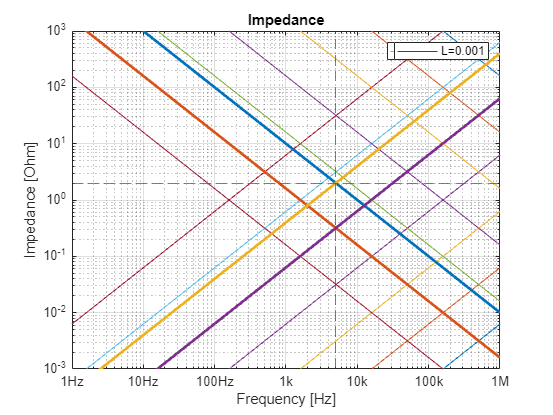




hold off

**Test**

a = 0

a = 0

for k = 1:2
    a = k + a
end

a = 1

a = 3

m1 = [1;2;3]

m1 =      1
     2
     3


m2 = [10;11;12]

m2 =     10
    11
    12


out = m1 * m2'

out =     10    11    12
    20    22    24
    30    33    36


% Make into column vector
out = out(:)

out =     10
    20
    30
    11
    22
    33
    12
    24
    36
